folder = ['dev' filesep 'MEEM_figs'];

phis = {'small-small','large-large'};
vels = {'small-small','large-small','large-large'};
figure 
tcl = tiledlayout(length(vels),length(phis)*2);
for i_phi = 1:length(phis)
    for i_vel = 1:length(vels)
        file = sprintf('*%s*.fig',['phi = ' phis{i_phi} ', vel = ' vels{i_vel}]);
        fname = dir(fullfile(folder,file)).name;
        fig = openfig(fname);
        
        ax = fig.Children(4);
        ax.Parent = tcl;
        ax.Layout.Tile = (i_vel-1)*2*length(phis) + 2*i_phi - 1;
        if i_vel==length(vels)
            xl = xlim;
            yl = ylim;
            text(ax, 1.25*xl(2), 1.25*yl(1), phis{i_phi})
        end
        if i_phi == 1
            ylabel(ax, {vels{i_vel}, 'Z'})
        end
        title(ax,'Real')

        ax2 = fig.Children(2);
        ax2.Parent = tcl;
        ax2.Layout.Tile = (i_vel-1)*2*length(phis) + 2*i_phi;
        title(ax2,'Imaginary')
    end
end

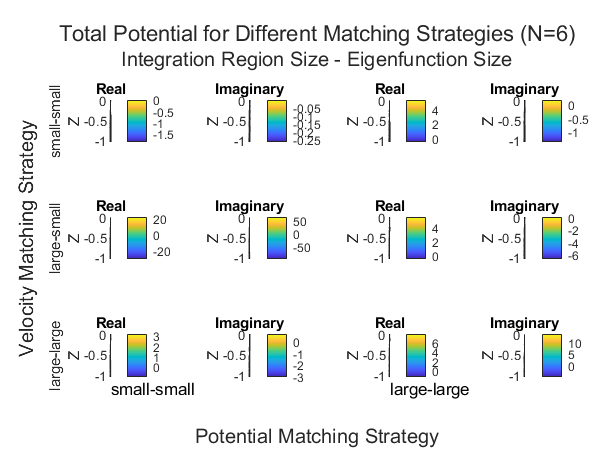

title(tcl,'Total Potential for Different Matching Strategies (N=6)')
subtitle(tcl,'Integration Region Size - Eigenfunction Size')
xlabel(tcl,'Potential Matching Strategy')
ylabel(tcl,'Velocity Matching Strategy')